# Set Options When Importing Text Data

Use the `setvaropts` function to update properties that control the import of text data. First, get the import options object for the file. Next, examine and update the options for the text variables. Finally, import the variables using the `readtable` function.

Preview the data in `patients.xls`. Notice the text data in the column `LastName`. Only a preview of the first 10 rows is shown here.

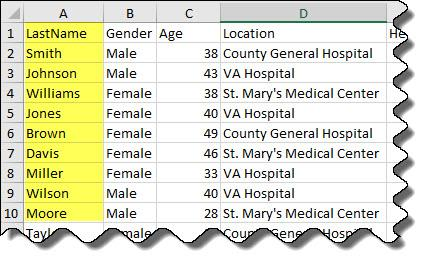

Get the import options object.

opts = detectImportOptions('patients.xls');

Get and examine the `VariableImportOptions` for variable `LastName`.

getvaropts(opts,'LastName')

Set the data type of the variable to `string`.

opts = setvartype(opts,'LastName','string');

Set the `FillValue` property of the variable to replace missing values with `'NoName'`.

opts = setvaropts(opts,'LastName','FillValue','NoName');

Select, read, and display a preview of the first 10 rows of the variable.

opts.SelectedVariableNames = 'LastName';
T = readtable('patients.xls',opts); 
T.LastName(1:10)

*Copyright 2012 The MathWorks, Inc.*